clc; clear all; close all;

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Ts = 0.2

Ts = 0.2000

A = [0.5, -1, 2;
      0.3, 0.7, -1;
      0.8, 0.9, 0.4];

B = [-1;-1;0.1];
C = [0.2, 0.3, 0.6];
D = [1.2];

nx = size(A,1)

nx = 3

ny = size(C,1)

ny = 1

nu = size(B,2)

nu = 1


% %LQGI
% AOL=[A zeros(nx,ny);-C zeros(ny,ny)]
% BOL=[B;zeros(ny,nu)]
% QOL=diag([100 100 100 10000])
% ROL=0.001*eye(nu);
% KOL=lqr(AOL,BOL,QOL,ROL)
% K=KOL(:,1:nx)
% Ki=-KOL(:,(nx+1):end)
% Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
% 
% Gw=eye(nx);
% Qw=0.01*eye(nx);
% Vv=.0001*eye(ny);
% L=lqe(A,Gw,C,Qw,Vv)
% 
% ACL=[A -B*K B*Ki;
%     L*C A-B*K-L*C B*Ki;
%     -C D*K -D*Ki];
% BCL=[B*Kr;B*Kr;eye(ny)-D*Kr];
% CCL=[C -D*K D*Ki]
% DCL=D*Kr;
% GCL=ss(ACL,BCL,CCL,DCL,Ts);
% abs(pole(GCL))
% step(minreal(GCL),10)

Qy=1000;
Ru=1;
Q=C'*Qy*C;
R=D'*Qy*D+Ru;
N=C'*Qy*D;
K=dlqr(A,B,Q,R,N)

K =    -0.9458   -0.2620   -1.0537


nx=size(A,1);
Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;

%% Comprobando si es observable nx = rank
rank(obsv(A,C))

ans = 3

nx=size(A,1)

nx = 3

ny=size(C,1)

ny = 1


G=eye(nx);
Qw=0.1*eye(nx);
Vv=0.0001*eye(ny);
L=dlqe(A,G,C,Qw,Vv);
ACL=[A -B*K;L*C A-B*K-L*C];
BCL=[B*Kr;B*Kr];
CCL=[C -D*K];
DCL=D*Kr;
GCL1 = minreal(ss(ACL,BCL,CCL,DCL,Ts));

3 states removed.


abs(pole(GCL1))

ans =     0.5064
    0.2141
    0.2141


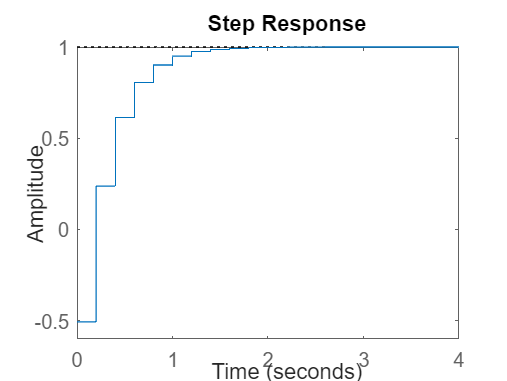

step(GCL1)



Qy = 1000000;
Ru = 0.001;
Qx = C' * Qy * C;
N_original = C' * Qy * D;
Qi = 10000 * eye(ny);
Qol = blkdiag(Qx, Qi);
R = D' * Qy * D + Ru;
Nol = [N_original; zeros(ny, nu)];
AOL = [A,          zeros(nx, ny);
       -C,         zeros(ny, ny)];
BOL = [B;
       zeros(ny, nu)];
KOL = lqr(AOL, BOL, Qol, R, Nol);
K = KOL(:, 1:nx);
Ki = -KOL(:, (nx+1):end);
Kr = (-(C - D*K) * ((A - B*K - eye(nx))\B) + D)^-1;

Gw = eye(nx);
Qw = 0.01 * eye(nx);
Vv = 0.0001 * eye(ny);
L = lqe(A, Gw, C, Qw, Vv);
ACL = [A,         -B*K,     B*Ki;
       L*C,   A - B*K - L*C,  B*Ki;
       -C,         D*K,     -D*Ki];
BCL = [B*Kr; B*Kr; eye(ny) - D*Kr];
CCL = [C, -D*K, D*Ki];
DCL = D*Kr;
GCL = ss(ACL, BCL, CCL, DCL, Ts);
abs(pole(GCL))

ans =     7.0896
    1.1867
    1.1867
    0.5087
    0.5087
    0.0157
    2.2225


3 states removed.


step(minreal(GCL))




P2 = exp(-4*s)/(s^3-2*s+0.8)
P2z = c2d(P2,Ts,'zoh')

%concatenacion
GCL2 = P2z*GCL1

A = GCL2.A;
B = GCL2.B;
C = GCL2.C
D = GCL2.D

Qy = 100;
Q = C'*Qy*C;
R = 0.1;

K = dlqr(A,B,Q,R);
nx = size(A,1);

Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
step(ss(A-B*K,B*Kr,C-D*K,D*Kr,Ts))


